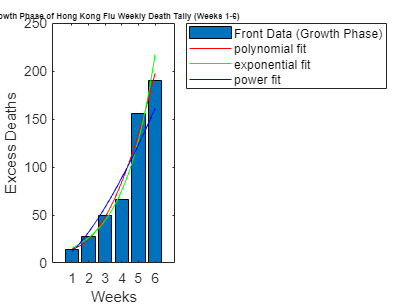

% Part 1: Linear and Logarithmic Fits of Existing Data For Alameda and NY
% Counties. (Growth Phase Oct. 2020 - Jan. 2021)
clear; clc; clear all;


% 1
clear; clc; clear all;
% import the data as tables, and convert into double arrays
Alameda_covid_data = readtable("ENGR_25_COVID_DATA_2.xlsx")

Alameda_covid_data = 1746×24 table
       date           area        area_type     population    cases    cumulative_cases    deaths    cumulative_deaths    total_tests    cumulative_total_tests    positive_tests    cumulative_positive_tests    reported_cases    cumulative_reported_cases    reported_deaths    cumulative_reported_deaths    reported_tests    Administered_Dose1_Recip_18PlusPop_Pct    GovernmentIntervention    Var20      Var21         Var22         Var23       total_adult_patients_hospitalized_confirmed_and_suspected_covid
    ___________    ______

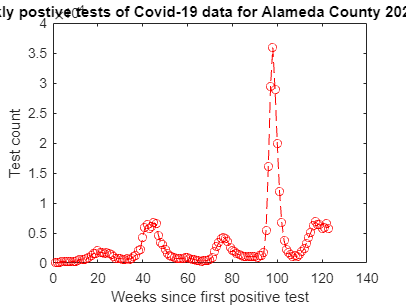

Apostests = table2array(Alameda_covid_data(28:1742, "positive_tests"));
Adeaths = table2array(Alameda_covid_data(28:1742, "deaths"));
Ahospitalization = table2array(Alameda_covid_data(28:1732, "total_adult_patients_hospitalized_confirmed_and_suspected_covid"));
Avaccinations = table2array(Alameda_covid_data(28:1742, "Administered_Dose1_Recip_18PlusPop_Pct"));


weeks = 1:length(Apostests)/7;
% convert column daily values to row vectors by week
postestweekly = reshape(sum(reshape(Apostests,7,[])),[],1)';
deathsweekly = reshape(sum(reshape(Adeaths,7,[])),[],1)';

hospitalizationweekly = reshape(sum(reshape(Ahospitalization,11,[])),[],1); % 11 hospitals per week
hospitalweeks = 1:140; % beyond this is future values, but not marked null, so we ignore

vaccinationsweekly = reshape(sum(reshape(Avaccinations,7,[])),[],1)';

% elimate null values (-9999) for hospitilization
for j = 1:length(hospitalizationweekly)
    if (hospitalizationweekly(j) < 0)
        hospitalizationweekly(j) = 0;
    end
end


plot(weeks, postestweekly, 'r--o');
xlabel('Weeks since first positive test');
ylabel('Test count');
title('Weekly postive tests of Covid-19 data for Alameda County 2020-2022');

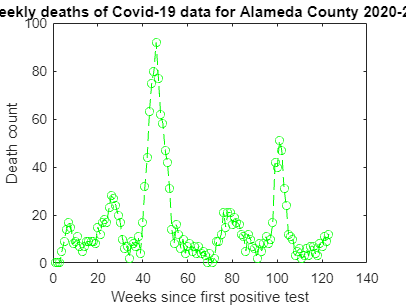


plot(weeks, deathsweekly, 'g--o');
xlabel('Weeks since first positive test');
ylabel('Death count');
title('Weekly deaths of Covid-19 data for Alameda County 2020-2022');

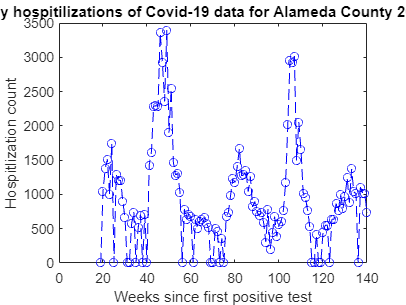


plot(hospitalweeks, hospitalizationweekly(1:140, 1), 'b--o');
xlabel('Weeks since first positive test');
ylabel('Hospitlization count');
title('Weekly hospitilizations of Covid-19 data for Alameda County 2020-2022');

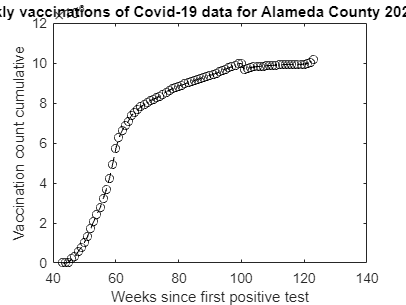


plot(weeks, vaccinationsweekly, 'k--o');
xlabel('Weeks since first positive test');
ylabel('Vaccination count cumulative');
title('Weekly vaccinations of Covid-19 data for Alameda County 2020-2022');


Newyork_covid_data = readtable('ENGR_25_COVID_DATA_2.xlsx','Sheet','New York City');

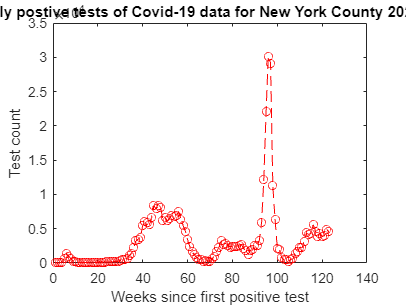

NYpostests = table2array(Newyork_covid_data(41:2868,"pnew_case"));
NYdeaths = table2array(Newyork_covid_data(41:2868,"new_death"));
NYhospitalization = table2array(Newyork_covid_data(41:2868, "total_adult_patients_hospitalized_confirmed_and_suspected_covid"));
NYvaccinations = table2array(Newyork_covid_data(41:2868,"Administered_Dose1_Recip_18Plus"));

weeks = 1:length(NYpostests)/7;
% convert column daily values to row vectors by week
NYpostestweekly = reshape(sum(reshape(NYpostests,7,[])),[],1)';
NYdeathsweekly = reshape(sum(reshape(NYdeaths,7,[])),[],1)';
NYhospitalizationweekly = reshape(sum(reshape(NYhospitalization,7,[])),[],1)';
NYvaccinationsweekly = reshape(sum(reshape(NYvaccinations,7,[])),[],1)';

% elimate null values (-9999) for hospitilization
for j = 1:length(NYhospitalizationweekly)
    if (NYhospitalizationweekly(j) < 0)
        NYhospitalizationweekly(j) = 0;
    end
end

plot(weeks, NYpostestweekly, 'r--o');
xlabel('Weeks since first positive test');
ylabel('Test count');
title('Weekly postive tests of Covid-19 data for New York County 2020-2022');

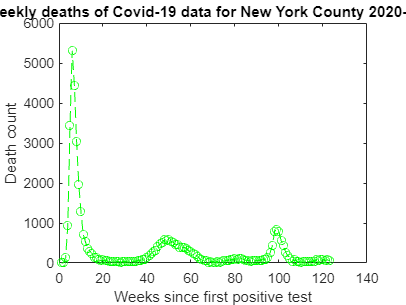


plot(weeks, NYdeathsweekly, 'g--o');
xlabel('Weeks since first positive test');
ylabel('Death count');
title('Weekly deaths of Covid-19 data for New York County 2020-2022');

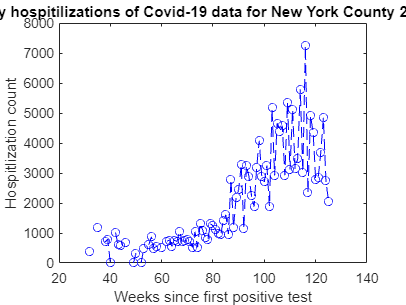


plot(weeks(1:125), NYhospitalizationweekly(1, 1:125), 'b--o'); % upper limit of hospital data for current dates
xlabel('Weeks since first positive test');
ylabel('Hospitlization count');
title('Weekly hospitilizations of Covid-19 data for New York County 2020-2022');

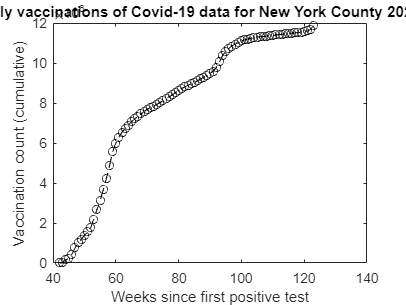


plot(weeks, NYvaccinationsweekly, 'k--o');
xlabel('Weeks since first positive test');
ylabel('Vaccination count (cumulative)');
title('Weekly vaccinations of Covid-19 data for New York County 2020-2022');

%2

% Alameda Growth Phase Oct 2020 - Jan 2021

% reimport data for the following start and end weeks from Oct 2020 - Jan
% 2021 
Alameda_covid_data = readtable("ENGR_25_COVID_DATA_2.xlsx")

Alameda_covid_data = 1746×24 table
       date           area        area_type     population    cases    cumulative_cases    deaths    cumulative_deaths    total_tests    cumulative_total_tests    positive_tests    cumulative_positive_tests    reported_cases    cumulative_reported_cases    reported_deaths    cumulative_reported_deaths    reported_tests    Administered_Dose1_Recip_18PlusPop_Pct    GovernmentIntervention    Var20      Var21         Var22         Var23       total_adult_patients_hospitalized_confirmed_and_suspected_covid
    ___________    ______

Afrontdeaths = table2array(Alameda_covid_data(245:363, "deaths"));
Afrontdeathsweekly = reshape(sum(reshape(Afrontdeaths,7,[])),[],1)';

frontweeks = 1:17;

% determine fit coefficients 
linfit = polyfit(frontweeks, Afrontdeathsweekly, 2);
expfit = polyfit(frontweeks, log10(Afrontdeathsweekly), 1);
powfit = polyfit(log10(frontweeks), log10(Afrontdeathsweekly), 1);

% create fit functions
Afrontlinval = @(weeks)linfit(1)*weeks^2 + linfit(2)*weeks + linfit(3);
Afrontexpval = @(weeks)10^expfit(2)*10^(expfit(1)*weeks);
Afrontpowval = @(weeks)10^powfit(2)*(weeks^powfit(1));

% plot graphs 
bar(frontweeks, Afrontdeathsweekly)
hold on
fplot(Afrontlinval, [1, 17], 'r')

fplot(Afrontexpval, [1, 17], 'g')

fplot(Afrontpowval, [1, 17], 'b')

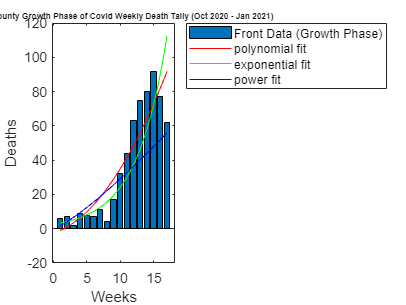

legend('Front Data (Growth Phase)', 'polynomial fit', 'exponential fit', 'power fit', 'Location','northeastoutside')
xlabel('Weeks')
ylabel('Deaths')
title('Alameda County Growth Phase of Covid Weekly Death Tally (Oct 2020 - Jan 2021)', 'FontSize', 6)
hold off


%% 3
% New York Growth Phase Oct 2020 - Jan 2021

% reimport data for the following start and end weeks from Oct 2020 - Jan
% 2021 
Newyork_covid_data = readtable('ENGR_25_COVID_DATA_2.xlsx','Sheet','New York City');

NYfrontdeaths = table2array(Newyork_covid_data(255:373, "new_death"));
NYfrontdeathsweekly = reshape(sum(reshape(NYfrontdeaths,7,[])),[],1)';

% determine fit coefficients 
linfit = polyfit(frontweeks, NYfrontdeathsweekly, 2);
expfit = polyfit(frontweeks, log10(NYfrontdeathsweekly), 1);
powfit = polyfit(log10(frontweeks), log10(NYfrontdeathsweekly), 1);

% create fit functions
NYfrontlinval = @(weeks)linfit(1)*weeks^2 + linfit(2)*weeks + linfit(3);
NYfrontexpval = @(weeks)10^expfit(2)*10^(expfit(1)*weeks);
NYfrontpowval = @(weeks)10^powfit(2)*(weeks^powfit(1));

% plot graphs 
bar(frontweeks, NYfrontdeathsweekly)
hold on
fplot(NYfrontlinval, [1, 17], 'r')

fplot(NYfrontexpval, [1, 17], 'g')

fplot(NYfrontpowval, [1, 17], 'b')

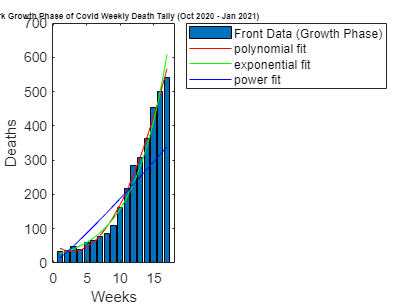

legend('Front Data (Growth Phase)', 'polynomial fit', 'exponential fit', 'power fit', 'Location','northeastoutside')
xlabel('Weeks')
ylabel('Deaths')
title('New York Growth Phase of Covid Weekly Death Tally (Oct 2020 - Jan 2021)', 'FontSize', 6)
hold off